load('building256.mat')
X = building256/255; 

% a 
C = X*X'

C =   242.8823  242.6921  242.5849  242.2224  242.3723  242.4943  242.3410  242.6505  242.0516  241.9173  242.3075  242.0858  241.6705  241.4808  242.0472  241.5925  241.5738  241.3600  241.0339  241.3646  241.5044  241.3191  241.5735  241.0302  240.9168  240.6572  241.0930  240.6316  240.1184  240.8563  240.2931  240.6434  239.9793  239.8676  239.5647  239.5783  239.8044  239.2448  239.7739  239.5007  240.2190  239.6034  239.6230  239.5635  238.3000  238.8723  239.0295  239.0736  240.6747  241.6739
  242.6921  242.5772  242.4313  242.0689  242.2204  242.3420  242.1862  242.4918  241.8996  241.7598  242.1614  241.9303  241.5160  241.3395  241.8986  241.4372  241.4294  241.2163  240.8794  241.2173  241.3543  241.1703  241.4212  240.8821  240.7564  240.5125  240.9422  240.4820  239.9665  240.7072  240.1464  240.4978  239.8265  239.7173  239.4166  239.4284  239.6567  239.0886  239.6235  239.3506  240.0672  239.4439  239.4769  239.4072  238.1435  238.7330  238.8790  238.9198  240.5263  241

% b 
[V, D] = eigs(C);
[d,ind] = sort(diag(D),'descend');
Ds = D(ind,ind);
Vs = V(:,ind);

sigma = diag(Ds);
sigma = sigma(1:5)

sigma = 	1.0e+04 *

    3.8236
    0.0679
    0.0247
    0.0070
    0.0035


u = Vs(:, 1:5)

u =     0.0796    0.0217   -0.0096    0.0394   -0.0825
    0.0795    0.0207   -0.0094    0.0380   -0.0781
    0.0795    0.0211   -0.0077    0.0380   -0.0782
    0.0794    0.0212   -0.0076    0.0360   -0.0738
    0.0794    0.0218   -0.0068    0.0371   -0.0734
    0.0795    0.0228   -0.0081    0.0382   -0.0746
    0.0794    0.0215   -0.0083    0.0404   -0.0775
    0.0795    0.0216   -0.0089    0.0362   -0.0775
    0.0793    0.0212   -0.0083    0.0373   -0.0782
    0.0793    0.0214   -0.0085    0.0379   -0.0755


% c 
V = zeros(size(u));
for i = 1:length(sigma)
    V(:,i)= sigma(i)^(-1/2)*X'*u(:,i);
end

% Each column in V represents vi where i is the column index 
V

V =     0.0607   -0.0760   -0.0344   -0.0090   -0.0956
    0.0618   -0.0802   -0.0367   -0.0047   -0.0819
    0.0615   -0.0751   -0.0409    0.0058   -0.0749
    0.0611   -0.0688   -0.0475    0.0245   -0.0459
    0.0606   -0.0650   -0.0467    0.0430   -0.0407
    0.0606   -0.0640   -0.0511    0.0456   -0.0379
    0.0605   -0.0586   -0.0497    0.0456   -0.0499
    0.0603   -0.0583   -0.0519    0.0478   -0.0407
    0.0605   -0.0576   -0.0522    0.0526   -0.0506
    0.0604   -0.0581   -0.0493    0.0539   -0.0463


% d 
X_i1 = sigma(1)^(1/2)*u(:,1)*V(:,1)';
X_i2 = sigma(2)^(1/2)*u(:,2)*V(:,2)';
X_i3 = sigma(3)^(1/2)*u(:,3)*V(:,3)';
X_i4 = sigma(4)^(1/2)*u(:,4)*V(:,4)';
X_i5 = sigma(5)^(1/2)*u(:,5)*V(:,5)';

X_k1 = X_i1

X_k1 =     0.9441    0.9619    0.9569    0.9504    0.9428    0.9431    0.9418    0.9381    0.9406    0.9398    0.9343    0.9330    0.9337    0.9357    0.9267    0.9353    0.9221    0.9210    0.9149    0.9140    0.9063    0.9045    0.9043    0.8988    0.8932    0.8958    0.8924    0.9032    0.9141    0.9338    0.9461    0.9658    0.9787    0.9912    1.0033    1.0124    1.0172    1.0174    1.0188    1.0199    1.0051    0.9991    0.9820    0.9722    0.9654    0.9525    0.9559    0.9470    0.9476    0.9485
    0.9436    0.9614    0.9565    0.9499    0.9424    0.9426    0.9413    0.9377    0.9401    0.9394    0.9339    0.9325    0.9333    0.9353    0.9262    0.9348    0.9216    0.9205    0.9144    0.9135    0.9058    0.9040    0.9038    0.8983    0.8927    0.8953    0.8920    0.9027    0.9137    0.9334    0.9457    0.9653    0.9782    0.9907    1.0028    1.0119    1.0167    1.0169    1.0183    1.0194    1.0045    0.9986    0.9815    0.9717    0.9649    0.9520    0.9554    0.9465    0.9472  

X_k2 = X_i1+X_i2

X_k2 =     0.9011    0.9165    0.9144    0.9115    0.9060    0.9068    0.9087    0.9051    0.9079    0.9070    0.9016    0.9015    0.8992    0.9014    0.8925    0.9034    0.8914    0.8910    0.8876    0.8873    0.8841    0.8818    0.8849    0.8795    0.8751    0.8793    0.8759    0.8815    0.8905    0.9010    0.9053    0.9161    0.9229    0.9293    0.9337    0.9422    0.9451    0.9449    0.9463    0.9484    0.9416    0.9389    0.9316    0.9296    0.9276    0.9233    0.9263    0.9261    0.9218    0.9248
    0.9026    0.9180    0.9159    0.9128    0.9072    0.9080    0.9097    0.9062    0.9089    0.9080    0.9026    0.9024    0.9003    0.9025    0.8935    0.9044    0.8923    0.8919    0.8884    0.8880    0.8846    0.8823    0.8853    0.8800    0.8754    0.8796    0.8762    0.8820    0.8912    0.9020    0.9067    0.9179    0.9249    0.9316    0.9364    0.9448    0.9479    0.9477    0.9491    0.9511    0.9440    0.9411    0.9334    0.9311    0.9288    0.9242    0.9272    0.9266    0.9225  

X_k3 = X_i1+X_i2+X_i3

X_k3 =     0.9063    0.9220    0.9206    0.9186    0.9131    0.9146    0.9162    0.9130    0.9158    0.9144    0.9091    0.9092    0.9062    0.9075    0.8989    0.9100    0.8986    0.8983    0.8960    0.8957    0.8927    0.8902    0.8940    0.8879    0.8835    0.8876    0.8837    0.8843    0.8903    0.8939    0.8944    0.9045    0.9131    0.9234    0.9313    0.9404    0.9418    0.9411    0.9430    0.9466    0.9455    0.9472    0.9455    0.9438    0.9352    0.9241    0.9181    0.9172    0.9176    0.9275
    0.9076    0.9235    0.9219    0.9198    0.9141    0.9156    0.9170    0.9138    0.9166    0.9153    0.9099    0.9099    0.9071    0.9085    0.8999    0.9109    0.8994    0.8990    0.8966    0.8963    0.8931    0.8906    0.8942    0.8882    0.8836    0.8877    0.8838    0.8847    0.8909    0.8951    0.8960    0.9065    0.9153    0.9258    0.9340    0.9431    0.9447    0.9439    0.9459    0.9494    0.9478    0.9493    0.9469    0.9449    0.9362    0.9249    0.9192    0.9178    0.9184  

X_k4 = X_i1+X_i2+X_i3+X_i4

X_k4 =     0.9033    0.9205    0.9225    0.9267    0.9273    0.9296    0.9312    0.9287    0.9332    0.9322    0.9269    0.9288    0.9252    0.9255    0.9188    0.9286    0.9181    0.9198    0.9188    0.9175    0.9178    0.9175    0.9197    0.9177    0.9153    0.9163    0.9130    0.9454    0.9523    0.9500    0.9317    0.9235    0.9168    0.9220    0.9443    0.9595    0.9609    0.9518    0.9390    0.9279    0.9141    0.9309    0.9407    0.9636    0.9747    0.9703    0.9466    0.8882    0.8769    0.8800
    0.9048    0.9220    0.9237    0.9275    0.9278    0.9301    0.9315    0.9290    0.9334    0.9324    0.9271    0.9289    0.9254    0.9258    0.9190    0.9288    0.9182    0.9198    0.9186    0.9173    0.9173    0.9169    0.9190    0.9168    0.9144    0.9154    0.9121    0.9437    0.9507    0.9492    0.9320    0.9249    0.9189    0.9245    0.9465    0.9615    0.9631    0.9543    0.9420    0.9314    0.9175    0.9335    0.9424    0.9640    0.9744    0.9695    0.9466    0.8899    0.8791  

X_k5 = X_i1+X_i2+X_i3+X_i4+X

X_k5 =     1.8759    1.9087    1.9107    1.8993    1.9155    1.9178    1.9038    1.9013    1.9214    1.9047    1.9152    1.9013    1.9134    1.9137    1.8914    1.9012    1.8907    1.9080    1.8914    1.8587    1.8904    1.8900    1.9079    1.8902    1.8878    1.8888    1.8542    1.9336    1.9248    1.9226    1.9043    1.8961    1.8580    1.8631    1.9168    1.9006    1.9335    1.8930    1.9115    1.9005    1.8867    1.9034    1.9133    1.9047    1.9473    1.9428    1.9191    1.8608    1.8494    1.8682
    1.8773    1.9102    1.8963    1.9001    1.9003    1.9026    1.9198    1.9016    1.9059    1.9206    1.9154    1.9014    1.8980    1.8983    1.8916    1.9014    1.8908    1.8923    1.8912    1.9055    1.8899    1.9051    1.8915    1.8894    1.8869    1.8565    1.8533    1.8849    1.9233    1.8904    1.9046    1.8661    1.8915    1.8970    1.9191    1.9027    1.9357    1.9425    1.9145    1.9039    1.8901    1.9060    1.9149    1.9365    1.9469    1.9420    1.9192    1.8625    1.8517  

% e 
fro_X = norm(X,'fro'); 

e_1 = norm((X_k1-X), 'fro')/fro_X

e_1 = 0.1742

e_2 = norm((X_k2-X), 'fro')/fro_X

e_2 = 0.1145

e_3 = norm((X_k3-X), 'fro')/fro_X

e_3 = 0.0828

e_4 = norm((X_k4-X), 'fro')/fro_X

e_4 = 0.0713

e_5 = norm((X_k5-X), 'fro')/fro_X

e_5 = 0.9975

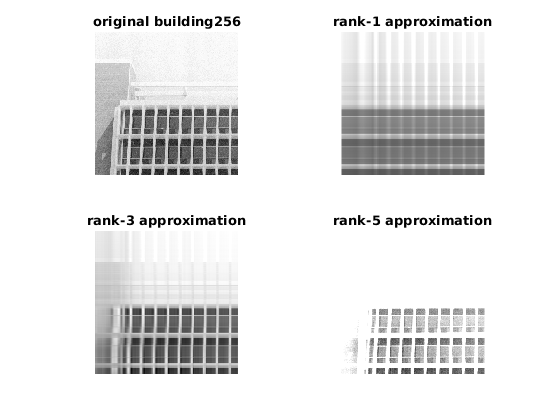

% f 
 figure(1)
 subplot(221)
 imshow(X)
 title("original building256")
 subplot(222)
 imshow(X_k1)
 title("rank-1 approximation")
 subplot(223)
 imshow(X_k3)
 title("rank-3 approximation")
 subplot(224)
 imshow(X_k5)
 title("rank-5 approximation") 

% g 
V_values = prod(size(V));
sigma_values = prod(size(sigma));
u_values = prod(size(u));

n5 = V_values + sigma_values + u_values;
compression_ratio = (256^2)/n5 

compression_ratio = 25.5501